# Hands on - preprocessing with EEG data

## Contents

- Band-pass filtering

- Data segmentation

- Singular value decomposition (SVD) and principal component analysis (PCA)

- Independent component analysis (ICA)

Add external libraries

eeglab;

Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "AAR" v131130 (see >> help eegplugin_aar)
EEGLAB: adding "AMICA" v1.7 (see >> help eegplugin_amica)
EEGLAB: adding "ANTeepimport" v1.14 (see >> help eegplugin_eepimport)
EEGLAB: adding "Adjust" v1.1.1 (see >> help eegplugin_adjust)
EEGLAB: adding "BDFimport" v1.2 (see >> help eegplugin_bdfimport)
EEGLAB: adding "Biosig" v3.8.4 to the path
EEGLAB: adding "EEG-BIDS" v9.1 (see >> help eegplugin_eegbids) - new version 10.1 available
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "MARA" v1.2 (see >> help eegplugin_MARA)
EEGLAB: adding "bva-io" v1.73 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata) - new version 2.10 available
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit) - new version 5.5 available
EEG

ft_defaults;

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

add_paths_Won2021;

Parameters

ch = 1:32; % select channels

Params_P3speller = struct('freq', [1 40], 'frame', [0 1000], ...
    'baseline', [-200 0], 'select_ch', 1:32);
electrodes_midline = {'FZ', 'Cz', 'Pz'};
electrodes_eyes = {'FP1', 'FP2', 'AF3', 'AF4'};

### Load one participant data

There are many runs in either test or train, but we will only load a single run for this hands-on


for nsb=1 % :55
    fname_train = sprintf('../data/s%02d.mat', nsb);
    EEG = load(fname_train);
    eeg_test = EEG.test;
    
    eeg_nontarget = [];
    for nRun = length(eeg_test) % 1:length(eeg_test)
        cur_eeg = eeg_test{nRun};
    end
end

## Visual inspection

- Frequency domain: power spectral density (PSD)

- Time domain: scroll display

close all;

data_untouched = cur_eeg.data; % [ch x time]
srate = cur_eeg.srate; % sampling frequency 
ch_locs = cur_eeg.chanlocs; % channel location and label info.

% Display data in frequency comain
figure,
spectopo(data_untouched, 0, srate);

Computing spectra (window length 512; fft length: 512; overlap 0):
................................
Click on each trace for channel/component index


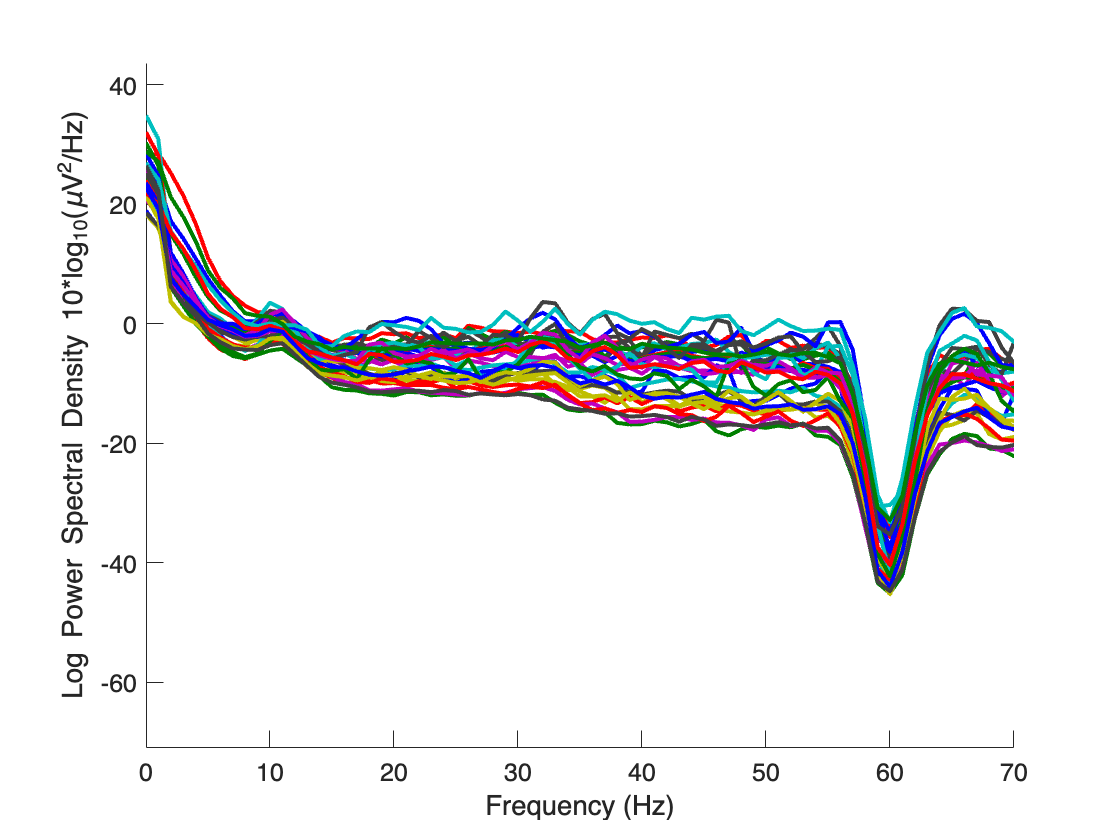

xlim([0, 70]);

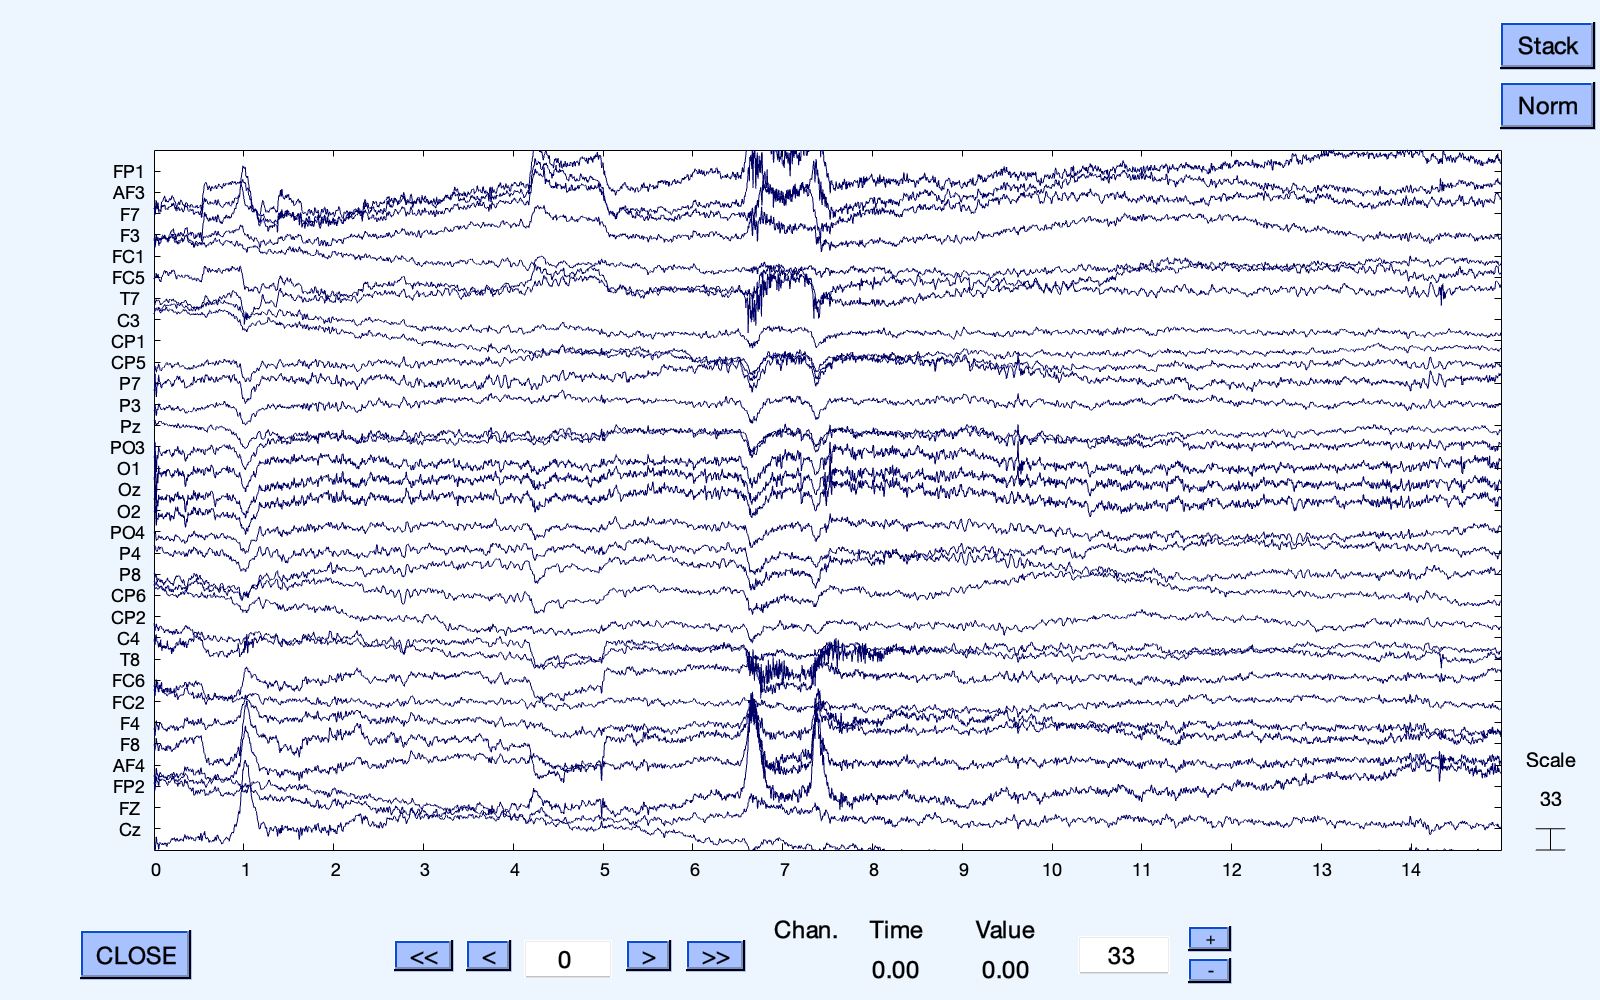

% Display data in time domain (scroll display)
eegplot(data_untouched, 'srate', srate, 'winlength', 15, 'eloc_file', ch_locs);

### Extract noisy period (huge amplitude fluctuation)

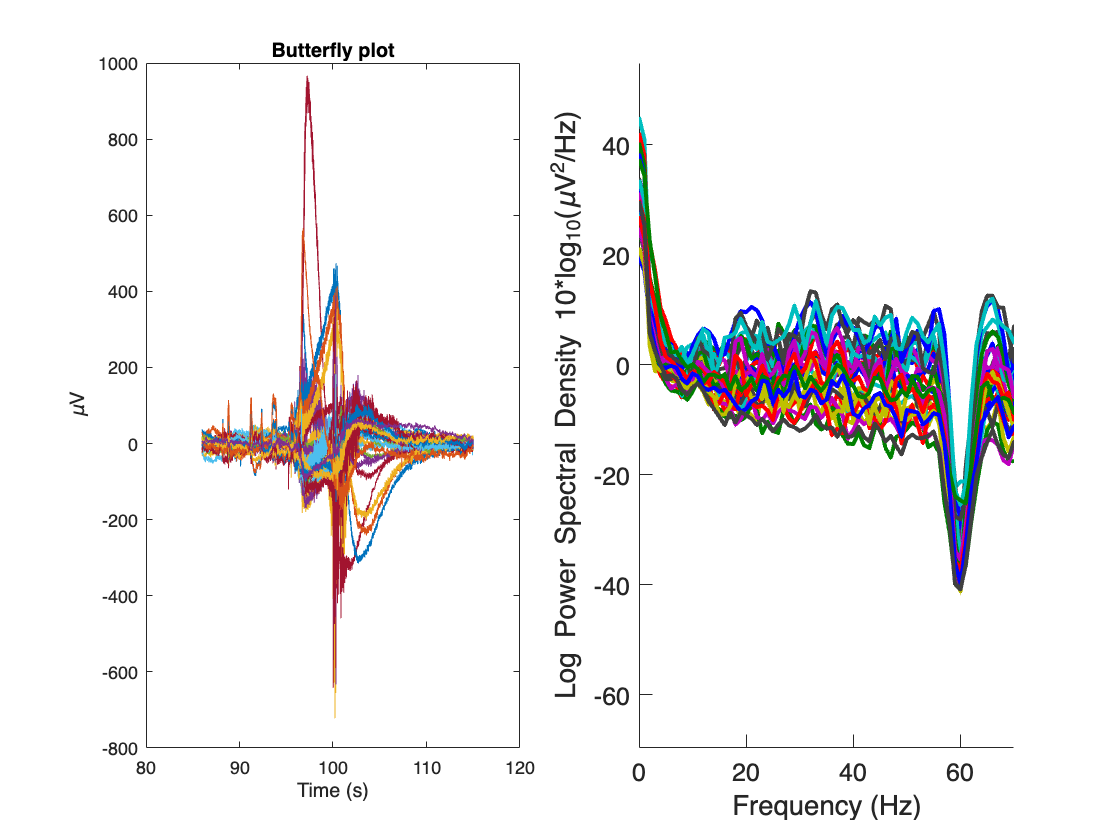

Computing spectra (window length 512; fft length: 512; overlap 0):
................................
Click on each trace for channel/component index


% We visually checked there is huge amplitude fluctuation around 80-100 s.

% Crop data containing the noise
data_nearby_artifacts = data_untouched(:, 86*srate:115*srate);
t = linspace(86, 115, size(data_nearby_artifacts, 2));

% Check in butterfly plot (all channels on the x-axis)
figure, 
subplot(1,2,1); plot(t, data_nearby_artifacts'); title('Butterfly plot');
xlabel('Time (s)'); ylabel('\muV'); 
subplot(1,2,2); spectopo(data_nearby_artifacts, 0, srate); xlim([0, 70]);

Now let's exclude huge amplitude noise manually, and check the influence on EEG data in time and frequency domain. However, it is not recommendable as we manully cropped data from continuous data. 

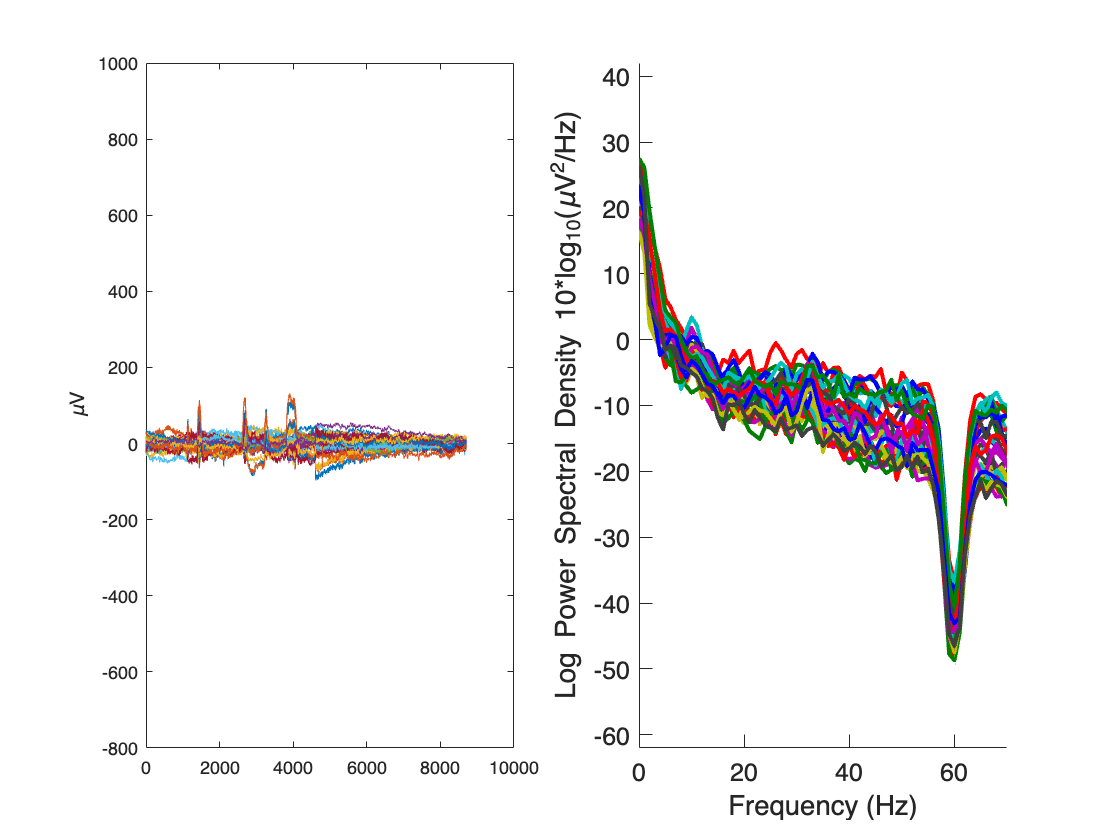

Computing spectra (window length 512; fft length: 512; overlap 0):
................................
Click on each trace for channel/component index


data_nearby_artifacts(:, 9*srate:21*srate) = []; % containing those artifacts

figure,
subplot(1,2,1); plot(data_nearby_artifacts'); ylim([-800, 1000]); % same ylim as above
ylabel('\muV');

subplot(1,2,2); spectopo(data_nearby_artifacts, 0, srate); ylim([-62, 42]); xlim([0, 70]);

You can see the difference!

## Phase shift caused by causal filtering

Causal filtering could make phase shift, meaning that filtered data have phase delay. It will affect your insights.

### Test with causal FIR lowpass filter

### Design Filter

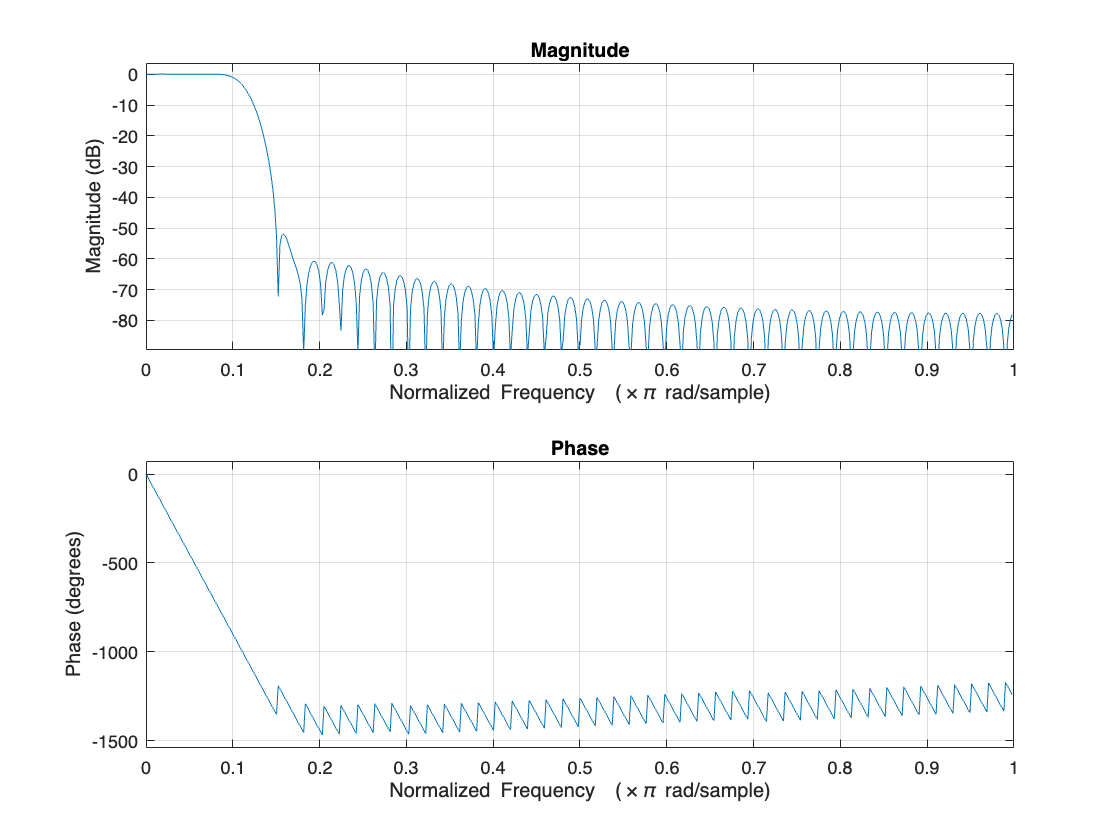

% Simple filter design
Fs = srate;
fc = 30; % cutoff frequency
order = 100;

b = fir1(order, fc/(Fs/2)); % FIR filter coefficients
figure,
freqz(b, 1, Fs); % filter property, s.t. frequency response

### Applying causal filter

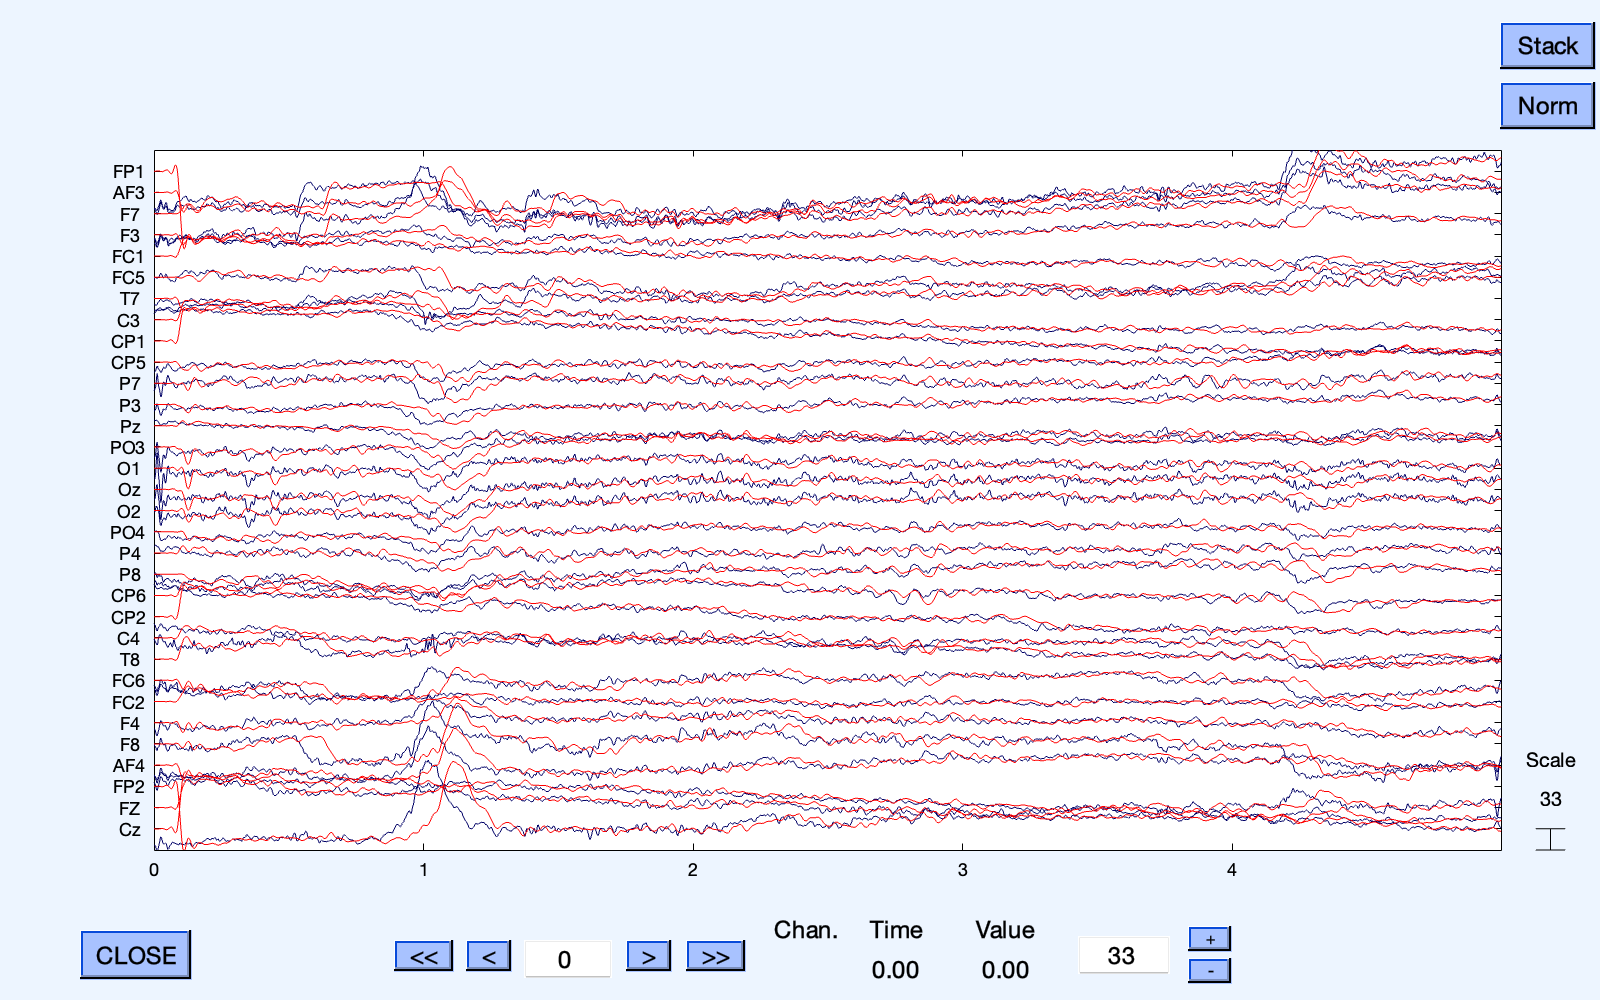

eeg_shifted = filter(b, 1, data_untouched');  % Apply causal filter
eegplot(data_untouched, 'data2', eeg_shifted', 'srate', cur_eeg.srate, 'eloc_file', cur_eeg.chanlocs);

Now you notice there is phase shift between blue and red lines, where blue lines indicate EEG before filtering and red lines indicate filtered data

### Applying zero-phase filter

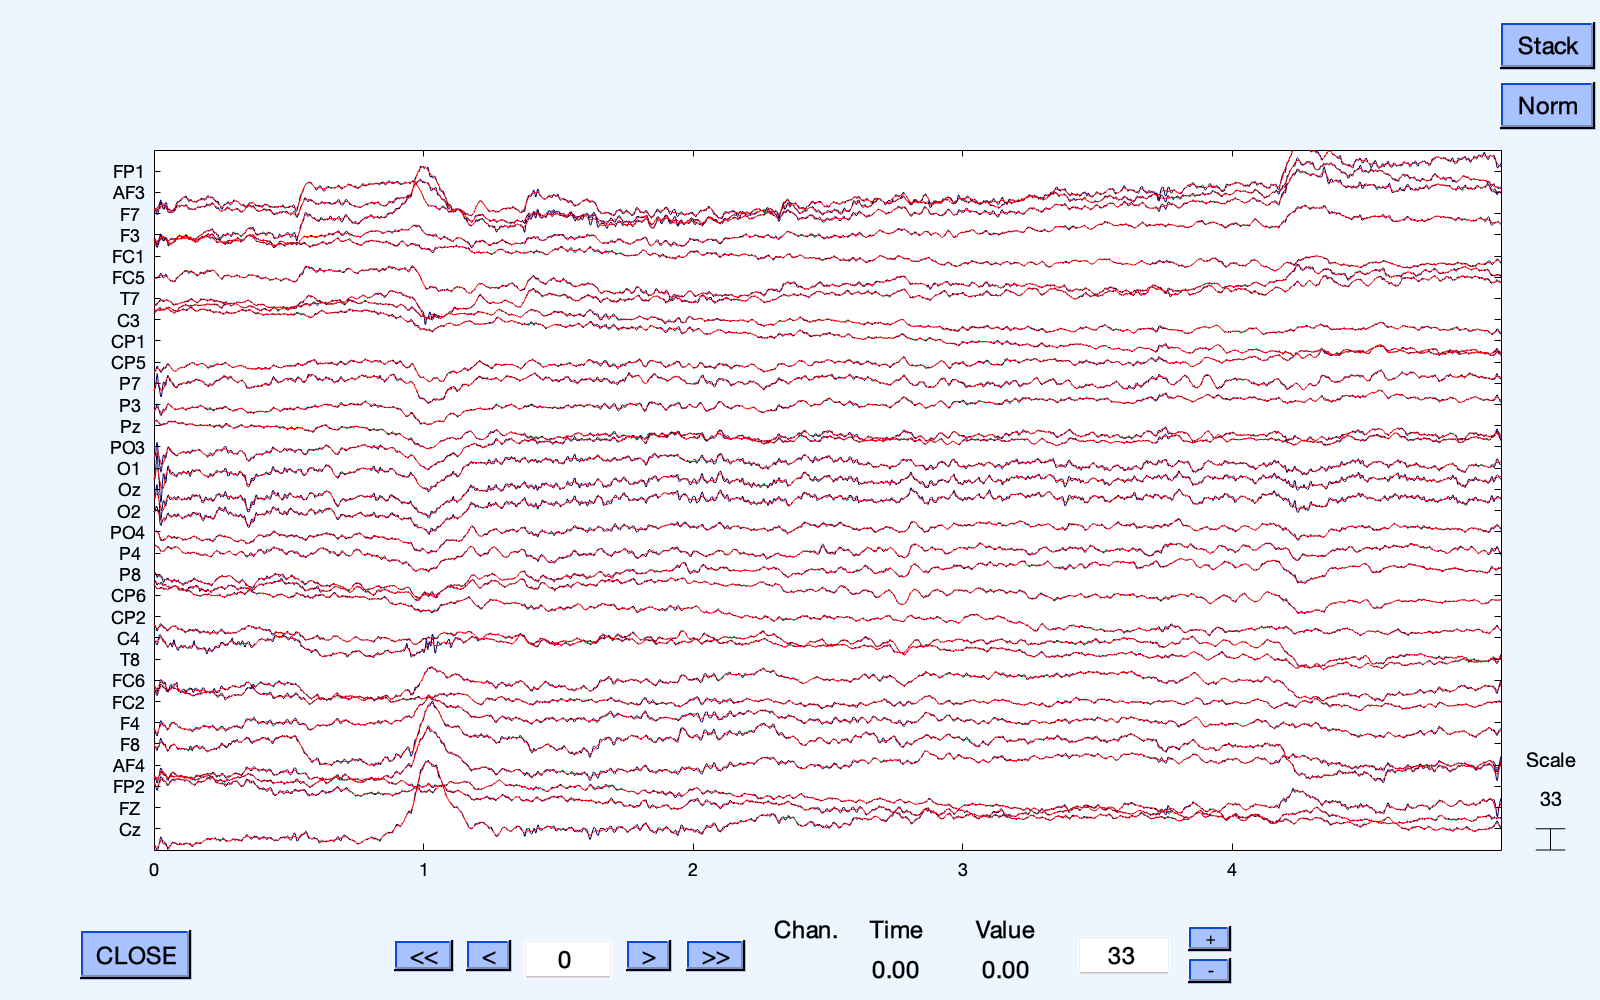

eeg_zero_phase_filtered = filtfilt(b, 1, data_untouched');  % Apply causal filter
eegplot(data_untouched, 'data2', eeg_zero_phase_filtered', ...
    'srate', cur_eeg.srate, 'eloc_file', cur_eeg.chanlocs);

By applying backward and foward filtering, you can avoid phase shift.

## Data segmentation